**Ajuste de Curvas:**

**Regresión por mínimos cuadrados:**

% Ejemplo 1:
xdata = [1 3 10 16]'

xdata =      1
     3
    10
    16


ydata = [4 7 12 18]'

ydata =      4
     7
    12
    18


% Método 1: Ecuaciones Normales:
% Ajuste Lineal:
A = [ sum(xdata.^0) sum(xdata.^1)
      sum(xdata.^1) sum(xdata.^2) ]

A =      4    30
    30   366


b = [ sum((xdata.^0).*ydata)
      sum((xdata.^1).*ydata) ]

b =     41
   433


coef = A\b

coef =     3.5745
    0.8901


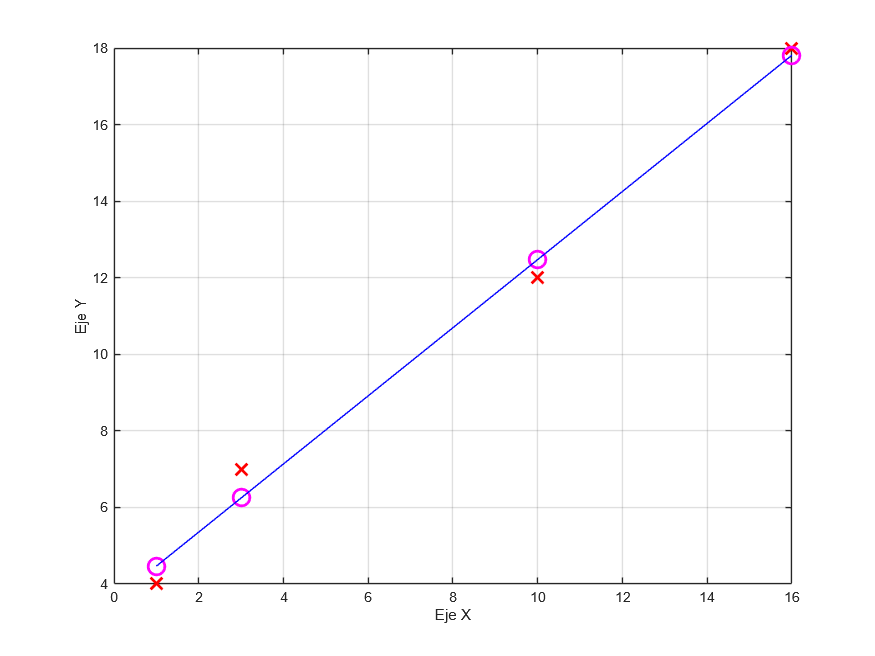

% Estimación de la recta:
yh = coef(1) + coef(2)*xdata;

figure(1); clf;
xx = xdata(1):0.1:xdata(end);
yy = coef(1) + coef(2)*xx;
plot(xdata,ydata,'xr','MarkerSize',12,'LineWidth',2); grid on; hold on;
plot(xdata,yh,'om','MarkerSize',12,'LineWidth',2);
plot(xx,yy,'-b'); 
xlabel('Eje X'); ylabel('Eje Y')

% Bondad del Ajuste:
St = sum((ydata - mean(ydata)).^2)

St = 112.7500

Sr = sum((ydata - yh).^2)

Sr = 1.0461

R2 = 1 - Sr/St

R2 = 0.9907

% Ajuste cuadrático:
A = [ sum(xdata.^0) sum(xdata.^1) sum(xdata.^2)
      sum(xdata.^1) sum(xdata.^2) sum(xdata.^3)
      sum(xdata.^2) sum(xdata.^3) sum(xdata.^4) ]

A =            4          30         366
          30         366        5124
         366        5124       75618


b = [ sum((xdata.^0).*ydata)
      sum((xdata.^1).*ydata)
      sum((xdata.^2).*ydata) ]

b =           41
         433
        5875


coef = A\b

coef =     3.6805
    0.8390
    0.0030


% Estimación de la curva:
fun = @(x) coef(1) + coef(2)*x + coef(3)*x.^2;
R2p = coef_deter(xdata,ydata,fun)

R2p = 0.9909

yh2 = fun(xdata)

yh2 =     4.5226
    6.2248
   12.3733
   17.8794


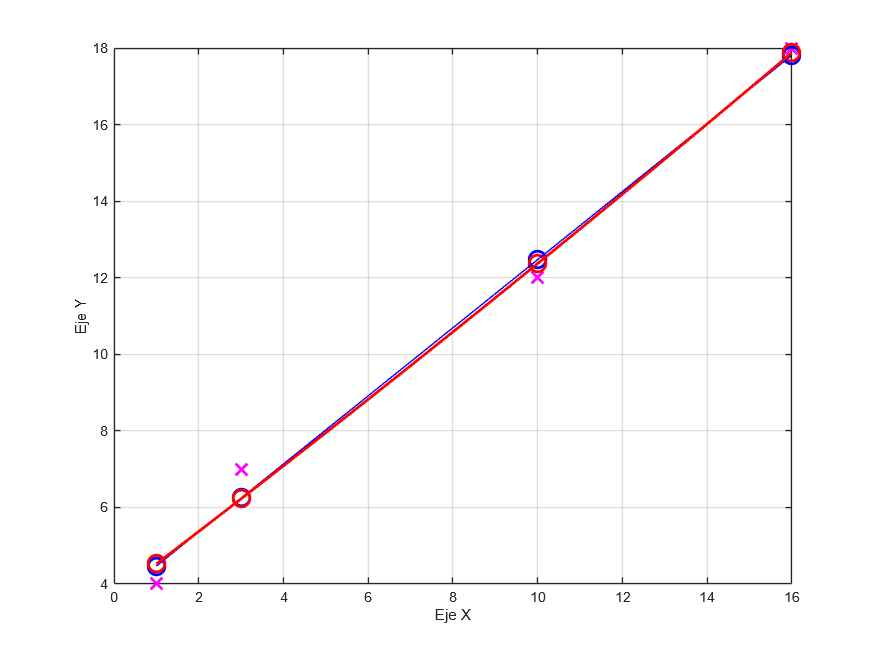

figure(2); clf;
xx2 = xdata(1):0.1:xdata(end);
yy2 = coef(1) + coef(2)*xx2 + coef(3)*xx2.^2;
plot(xdata,ydata,'xm','MarkerSize',12,'LineWidth',2); grid on; hold on;
plot(xdata,yh,'ob','MarkerSize',12,'LineWidth',2);
plot(xdata,yh2,'or','MarkerSize',12,'LineWidth',2);
plot(xx,yy,'-b');
plot(xx2,yy2,'-r','LineWidth',2); 
xlabel('Eje X'); ylabel('Eje Y')

% Método 2: Sistema Sobredeterminado:
xdata = [1 3 10 16]'

xdata =      1
     3
    10
    16


ydata = [4 7 12 18]'

ydata =      4
     7
    12
    18


% Ajuste Lineal:
A = [ xdata.^0 xdata.^1 ]

A =      1     1
     1     3
     1    10
     1    16


b = ydata

b =      4
     7
    12
    18


coef = (A'*A)\(A'*b)

coef =     3.5745
    0.8901


% Ajuste Cuadrático:
A = [ xdata.^0 xdata.^1 xdata.^2 ]

A =      1     1     1
     1     3     9
     1    10   100
     1    16   256


b = ydata

b =      4
     7
    12
    18


coef = (A'*A)\(A'*b)

coef =     3.6805
    0.8390
    0.0030


% Método con Matlab:
% Ajuste Lineal:
n = 1;
pol1 = polyfit(xdata,ydata,n)

pol1 =     0.8901    3.5745


% Ajuste Cuadrático:
n = 2;
pol2 = polyfit(xdata,ydata,n)

pol2 =     0.0030    0.8390    3.6805


% polyfit: interpolación polinomial o ajuste/regresión polinomial

FUNCIONES:

function R2 = coef_deter(x,y,fun)
    yh = fun(x);
    St = sum((y - mean(y)).^2);
    Sr = sum((y - yh).^2);
    R2 = 1 - Sr/St;
end